**Федеральное агентство железнодорожного транспорта**

Федеральное государственное бюджетное образовательное учреждение

высшего образования

«**Петербургский** **государственный университет путей сообщения Императора Александра ****I****»**

**(ФГБОУ ВО ПГУПС)**

­­­­­­­­­­­­––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––

Факультет «Транспортные и энергетические системы» 

Кафедра «Электрическая тяга»

**ОТЧЁТ**

**по лабораторной работе №2**

**«**Исследование однофазного двухполупериодного управляемого выпрямителя**»**

**Вариант №4**

Выполнили:

студенты гр. ПС-003 

Дулепов И.Г.

Минина А.С.

Проверил:

Сычугов А.Н.

Санкт-Петербург

2024

**1. Цель работы - **Исследование на компьютерной модели однофазного управляемого  выпрямителя при работе на активно-индуктивную нагрузку с противо-э.д.с. и обратным диодом.

**2. Содержание работы: **

2.1. Исследование внешних и энергетических характеристик однофазного управляемого выпрямителя при работе на активно-индуктивную  нагрузку с противо-э.д.с. и обратным диодом. 

2.2. Исследование регулировочных характеристик однофазного управляемого выпрямителя при работе на активно-индуктивную нагрузку с  противо-э.д.с. и обратным диодом. 

2.3. Исследование гармонического состава тока потребления однофазного управляемого выпрямителя

**3. Задание исходных данных:**

Открываем файл с заданными параметрами:

open('ЛР 2 комп.моделирование\Задание к ЛР2.txt')

Используем исходные данные, импортируемые из текстового файла задания:

C = readcell('ЛР 2 комп.моделирование\Задание к ЛР2.txt');
i = C(6:14, 3);
data.U_AC = i{1,1};
data.f_AC = i{2,1};
data.S = i{3,1};
data.U_1 = i{5,1};
data.K_t = i{6,1};
data.R_n = i{8,1};
data.E = i{9,1};
data.T = table(data.U_AC.',data.f_AC.',data.S.', data.U_1.', data.K_t.', data.R_n.',data.E.');
data.T.Properties.VariableNames = ["U_AC,В","f_AC,Гц","S,кВт","U_1,В","K_т","R_н,Ом","E,В"];
disp(data.T);

    U_AC,В    f_AC,Гц    S,кВт    U_1,В    K_т    R_н,Ом    E,В
    ______    _______    _____    _____    ___    ______    ___

     220        100       200      220      1       2       35 



Задаём параметры источника напряжения:

ACsource.voltage = data.U_AC*1.41;
ACsource.freq = data.f_AC;

Задаём параметры трансформатора:

transparam.power = data.S * 10^3;
transparam.volt1wing = data.U_1;
K_T = data.K_t;
transparam.volt2wing = transparam.volt1wing / K_T;

Задаём параметры нагрузки:

Параметры сопротивления:

load.Res = data.R_n;
load.Ind = (load.Res/ACsource.freq) * 2; %(в диапазоне от 2 до 5)

Параметры ЭДС:

DCsource.voltage = data.E;
Eds2 = [];
Eds2 = DCsource.voltage;

Задаем угол управления выпрямителем:

Angle.Alpha = 0;

**4. Таблицы опытных и расчетных данных.**

Подготавливаем массивы для снятия параметров измерений в таблицу 1.  (снятие внешних характеристик при изменении E и alpha)

Alpha = [];
E = [];
I_n = [];
U_n = [];
I_1max = [];
Phi_1 = [];
I_VSD = [];
I_VS = [];
U_VSmax = [];
I_VSmax = [];
S_1 = [];
p_1 = [];
P_n = [];
P_t = [];
U1_max = [];
Uf = [];
Ron = [];

Открываем файл исследуемой модели:

open("ЛР 2 комп.моделирование\LR2VideoBlock.mlx")

Изменяеем противо-э.д.с. нагрузки от 0 В до 100 В с шагом  20 В. Внешние характеристики снимаем для трех значений угла управления  выпрямителем (α= 0°, 40°, 60°). Результаты вычислений записываются в таблицу 1.

Полную и активную мощности по первой гармонике, потребляемые  выпрямителем из сети, рассчитываем по выражениям:

Мощность в нагрузке определяем по выражению: 

Потери в тиристоре УВ рассчитываем по выражению:

Задаем шаг с которым будут изменятся значения угла регулирования и противо-эдс вращения:

astep = 20;
amin = 0;
amax = 60;
anumStep=round((amax-amin)/astep+1)

anumStep = 4

EStep=20; 
Emin=0;
Emax=100;
EnumStep=round((Emax-Emin)/EStep+1)

EnumStep = 6

for a = amin:astep:amax
    Angle.Alpha = a;
        Alpha(end+EStep) = Angle.Alpha;
        Alpha = repelem(amin:astep:amax,EnumStep);
        for eds = Emin:EStep:Emax
        DCsource.voltage = eds;
        E(end+1) = DCsource.voltage(end, 1);
        U1_max(end+1) = ACsource.voltage(end, 1);
        sim('Lab2Videoblock.slx')
        I_n(end+1) = max(loadCurrent(end, 1));
        U_n(end+1)= max(loadVoltage(end, 1));
        I_1max(end+1) = max(sourceCurrent(end, 1));
        Phi_1(end+1) = max(sourcePhase(end, 1));
        I_VSD(end+1) = max(currentVSD(end, 1));
        I_VS (end+1) = mean(CurrentVSmax(end, 1));
        U_VSmax(end+1) = max(VoltageVSmax(end, 1));
        I_VSmax(end+1) = max(CurrentVSmax(end, 1));
        S_1(end+1) = ACsource.voltage(end, 1)*max(sourceCurrent(end, 1))/2;
        p_1(end+1) = abs((ACsource.voltage(end, 1)*max(sourceCurrent(end, 1))/2) * (cos(max(sourcePhase(end, 1)))));
        P_n(end+1) = max(loadCurrent(end, 1))*max(loadVoltage(end, 1));
        Uf = 1;
        Ron = 0.001;
        P_t(end+1) =  Uf*max(CurrentVSmax(end, 1))+Ron*(max(currentVSD(end, 1))^2);
        end
    end

Данные, полученные при моделировании компьютерной модели однофазного управляемого двухполупериодного выпрямителя, представлены в таблице 1.

Результаты вычислений. Таблица 1.

                    T1 = table(Alpha.',E.', I_n.', U_n.', I_1max.', Phi_1.',I_VSD.',I_VS.', U_VSmax.', I_VSmax.',S_1.',p_1.',P_n.',P_t.');
T1.Properties.VariableNames = ["Alpha","E", "I_n", "U_n", "I_1max", "Phi_1","I_VSD","I_VS", "U_VSmax", "I_VSmax","S_1","p_1","P_n","P_t"];
disp(T1);

    Alpha     E      I_n       U_n      I_1max     Phi_1     I_VSD      I_VS     U_VSmax    I_VSmax     S_1      p_1       P_n      P_t  
    _____    ___    ______    ______    ______    _______    ______    ______    _______    _______    _____    ______    _____    ______

      0        0    94.199    188.42    120.03    -2.6355    66.007    59.987    152.09     59.987     18617     16283    17749    64.343
      0       20    103.95    187.91    132.44    -2.6318    72.825    66.191    151.79     66.191     20541 

Исследование регулировочной характеристики управляемого однофазного выпрямителя производим при одном значении противо-э.д.с. (E) и изменении угла управления от 0 до 180 градусов с шагом 20 градусов. 

Подготавливаем массивы для снятия параметров измерений в таблицу 2.

Alpha2 = [];
E2 = [];
U_n2 = [];

Моделирование осуществляем при каждом значении угла управления, при этом заполняем таблицу 2.

for a = 0:20:180
    Angle.Alpha = a;
    Alpha2(end+1) = Angle.Alpha;
    E2(end+1) = Eds2(end, 1);
    sim 'ЛР 2 комп.моделирование'\Lab2Videoblock.slx
    U_n2(end+1)= max(loadVoltage(end, 1));
end     

Заносим результаты моделирования в таблицу 2.

Результаты вычислений. Таблица 2.

T2 = table(Alpha2.',E2.',U_n2.');
T2.Properties.VariableNames = ["Alpha","E","U_n"];
disp(T2);

    Alpha    E       U_n  
    _____    __    _______

       0     35     187.54
      20     35     182.72
      40     35     166.86
      60     35     141.95
      80     35     111.05
     100     35      77.95
     120     35      46.71
     140     35     21.215
     160     35     4.6565
     180     35    0.81709



**6. Построение нагрузочных, энергетических и регулировочных характеристик:**

Нагрузочная характеристика представлена на графике ниже:

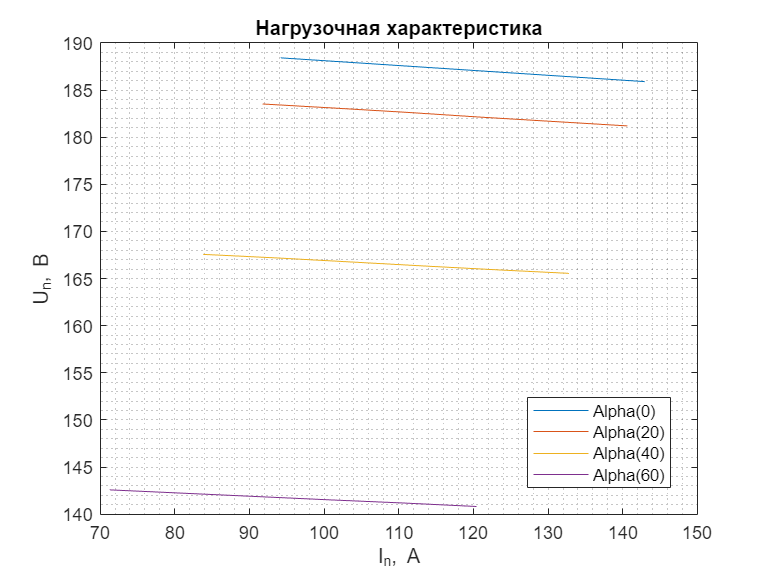

x1 = T1.I_n(1:6);
y1 = T1.U_n(1:6);
x2 = T1.I_n(7:12);
y2 = T1.U_n(7:12);
x3 = T1.I_n(13:18);
y3 = T1.U_n(13:18);
x4 = T1.I_n(19:24);
y4 = T1.U_n(19:24);
plot(x1,y1,x2,y2,x3,y3,x4,y4)
grid("minor");
xlabel('I_n, А');
ylabel('U_n, В');
title('Нагрузочная характеристика');
legend(["Alpha(0)","Alpha(20)","Alpha(40)","Alpha(60)"])
legend("Position",[0.68524,0.15579,0.18571,0.15595])

Энергетические характеристики:

Энергетические характеристики для Pт = f(Pн) :

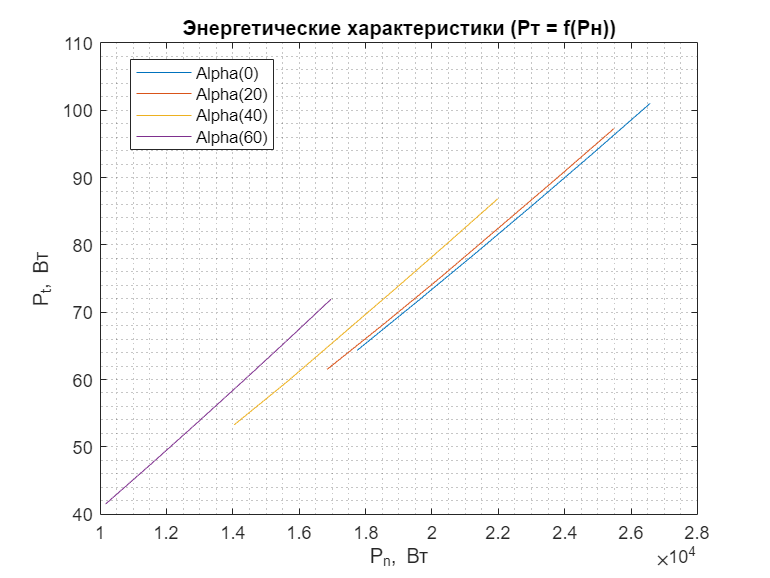

x1 = T1.P_n(1:6);
y1 = T1.P_t(1:6);
x2 = T1.P_n(7:12);
y2 = T1.P_t(7:12);
x3 = T1.P_n(13:18);
y3 = T1.P_t(13:18);
x4 = T1.P_n(19:24);
y4 = T1.P_t(19:24);
plot(x1,y1,x2,y2,x3,y3,x4,y4)
grid("minor");
xlabel('P_n, Вт');
ylabel('P_t, Вт');
title('Энергетические характеристики (Pт = f(Pн))');
legend(["Alpha(0)","Alpha(20)","Alpha(40)","Alpha(60)"])
legend("Position",[0.16952,0.74056,0.18571,0.15595])

Энергетические характеристики для S1 = f(Pн) :

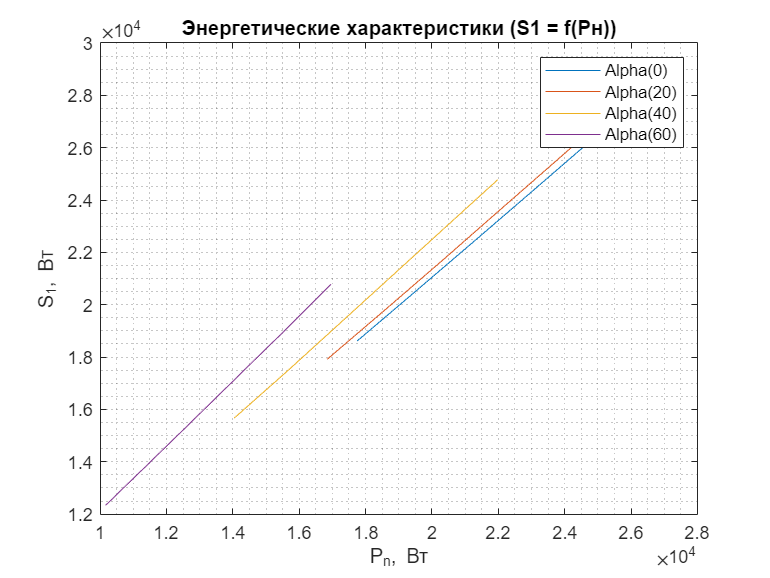

x1 = T1.P_n(1:6);
y1 = T1.S_1(1:6);
x2 = T1.P_n(7:12);
y2 = T1.S_1(7:12);
x3 = T1.P_n(13:18);
y3 = T1.S_1(13:18);
x4 = T1.P_n(19:24);
y4 = T1.S_1(19:24);
plot(x1,y1,x2,y2,x3,y3,x4,y4)
grid("minor");
xlabel('P_n, Вт');
ylabel('S_1, Вт');
title('Энергетические характеристики (S1 = f(Pн))');
legend(["Alpha(0)","Alpha(20)","Alpha(40)","Alpha(60)"])

Энергетические характеристики для P1 = f(Pн) :

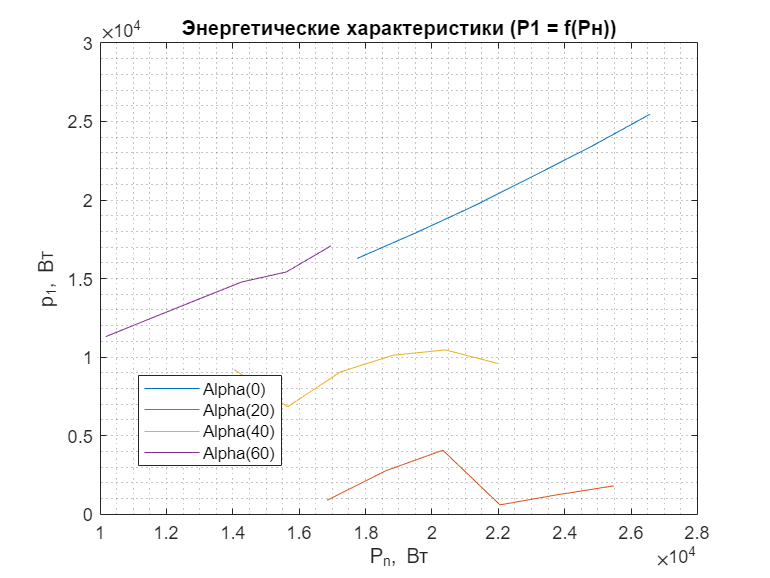

x1 = T1.P_n(1:6);
y1 = T1.p_1(1:6);
x2 = T1.P_n(7:12);
y2 = T1.p_1(7:12);
x3 = T1.P_n(13:18);
y3 = T1.p_1(13:18);
x4 = T1.P_n(19:24);
y4 = T1.p_1(19:24);
plot(x1,y1,x2,y2,x3,y3,x4,y4)
grid("minor");
xlabel('P_n, Вт');
ylabel('p_1, Вт');
title('Энергетические характеристики (P1 = f(Pн))');
legend(["Alpha(0)","Alpha(20)","Alpha(40)","Alpha(60)"])
legend("Position",[0.17952,0.19389,0.18571,0.15595])

Регулировочные характеристики зависимости IVSD, I1max и IVS = f(Iн) для различных углов представлены ниже:

Для угла α = 0:

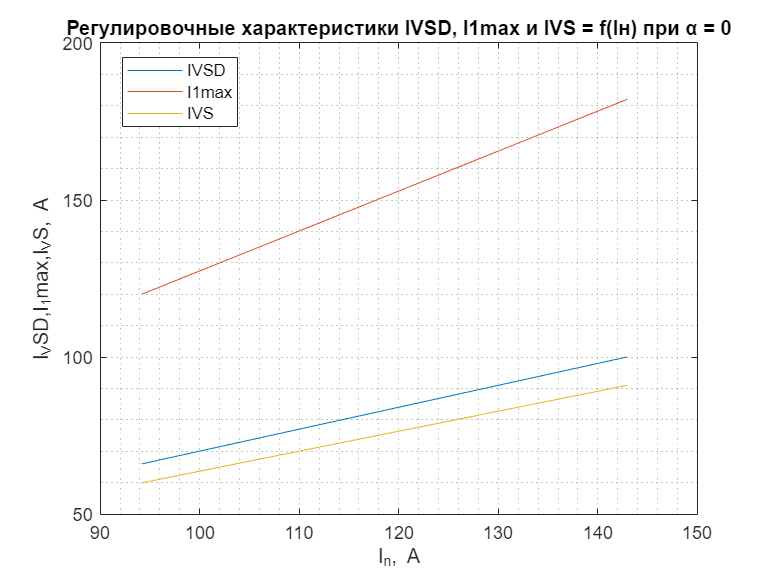

x1 = T1.I_n(1:6);
y1 = T1.I_VSD(1:6);
x2 = T1.I_n(1:6);
y2 = T1.I_1max(1:6);
x3 = T1.I_n(1:6);
y3 = T1.I_VS(1:6);
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('I_n, А');
ylabel('I_VSD,I_1max,I_VS, А');
title('Регулировочные характеристики IVSD, I1max и IVS = f(Iн) при α = 0');
legend(["IVSD","I1max","IVS"])
legend("Position",[0.1581,0.78127,0.15,0.11905])

Для угла α = 20:

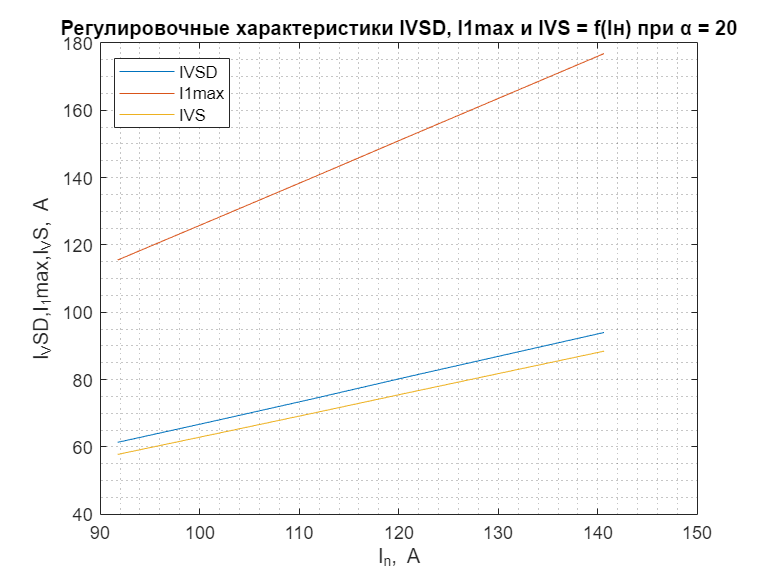

x1 = T1.I_n(7:12);
y1 = T1.I_VSD(7:12);
x2 = T1.I_n(7:12);
y2 = T1.I_1max(7:12);
x3 = T1.I_n(7:12);
y3 = T1.I_VS(7:12);
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('I_n, А');
ylabel('I_VSD,I_1max,I_VS, А');
title('Регулировочные характеристики IVSD, I1max и IVS = f(Iн) при α = 20');
legend(["IVSD","I1max","IVS"])
legend("Position",[0.1481,0.77937,0.15,0.11905])

Для угла α = 40:

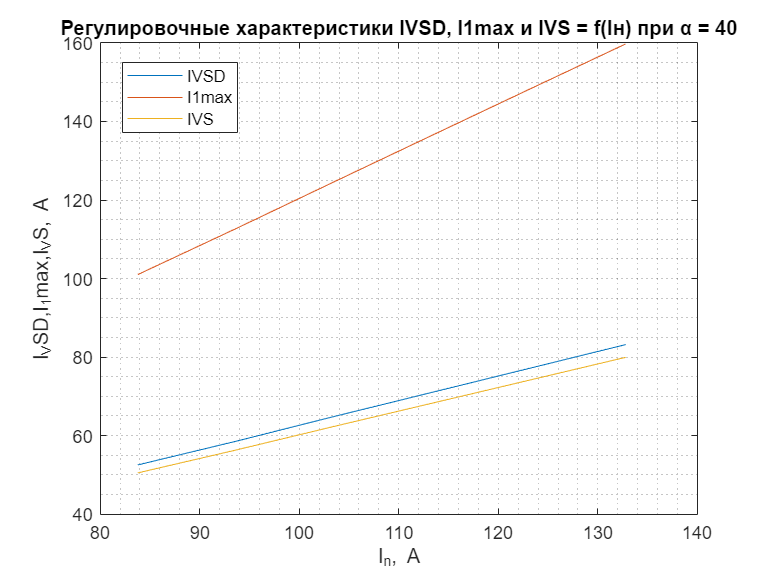

x1 = T1.I_n(13:18);
y1 = T1.I_VSD(13:18);
x2 = T1.I_n(13:18);
y2 = T1.I_1max(13:18);
x3 = T1.I_n(13:18);
y3 = T1.I_VS(13:18);
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('I_n, А');
ylabel('I_VSD,I_1max,I_VS, А');
title('Регулировочные характеристики IVSD, I1max и IVS = f(Iн) при α = 40');
legend(["IVSD","I1max","IVS"])
legend("Position",[0.1581,0.77175,0.15,0.11905])

Для угла α = 60:

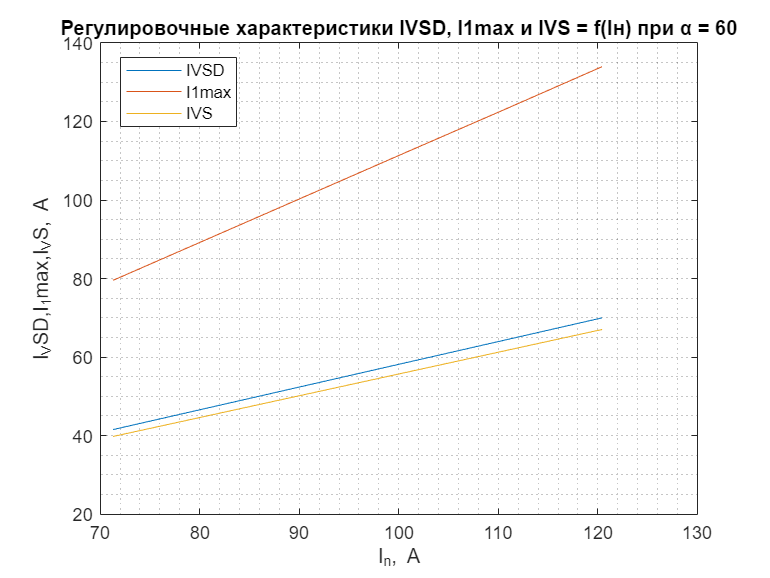

x1 = T1.I_n(19:24);
y1 = T1.I_VSD(19:24);
x2 = T1.I_n(19:24);
y2 = T1.I_1max(19:24);
x3 = T1.I_n(19:24);
y3 = T1.I_VS(19:24);
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('I_n, А');
ylabel('I_VSD,I_1max,I_VS, А');
title('Регулировочные характеристики IVSD, I1max и IVS = f(Iн) при α = 60');
legend(["IVSD","I1max","IVS"])
legend("Position",[0.15667,0.78127,0.15,0.11905])

**7. Диаграммы токов и напряжений на входе трансформатора, нагрузки, тиристора управляемого выпрямителя, обратного диода, а также сигналов системы управления для углов регулирования (α= 0°, 40°, 60°) и E=0 В.**

При угле альфа = 0 и ЭДС = 0:

Мгновенные токи и напряжение управляемого выпрямителя:

Диаграммы тока на входе трансформатора ,тока обратного диода, тока и напряжения на нагрузке:

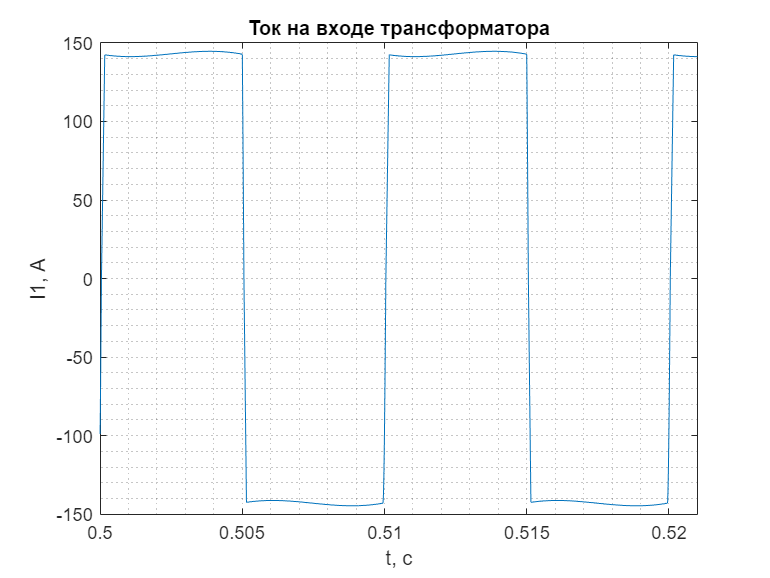

for a = 0
    Angle.Alpha = a;
    sim 'ЛР 2 комп.моделирование'\Lab2Videoblock.slx;
    DCsource.voltage = 0;
    E = DCsource.voltage;
end  
    plot(ScopeVS{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('I1, А');
    title('Ток на входе трансформатора');
    xlim([0.5 0.521]);

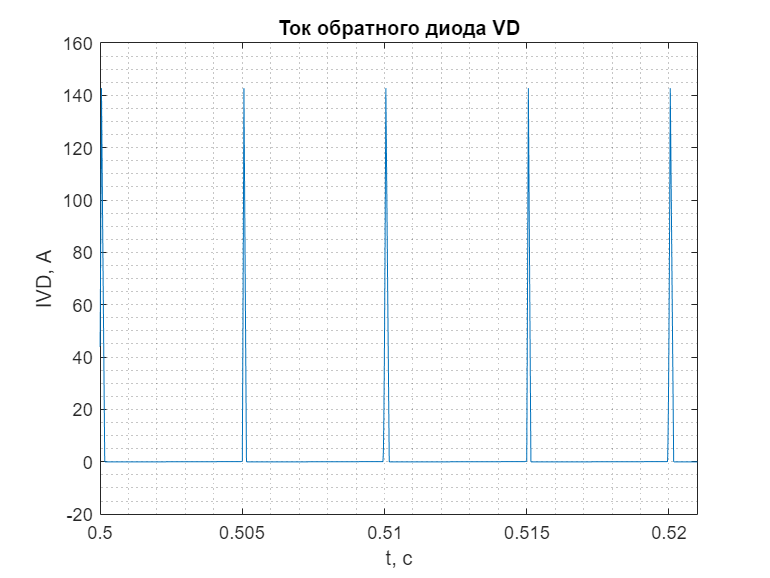

    plot(ScopeVS{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('IVD, А');
    title('Ток обратного диода VD');
    xlim([0.5 0.521]);

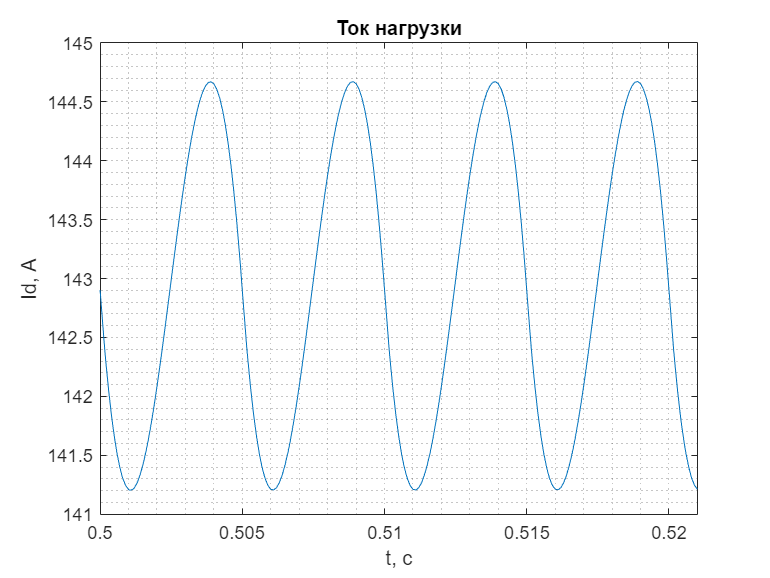

    plot(ScopeVS{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Id, А');
    title('Ток нагрузки');
    xlim([0.5 0.521]);

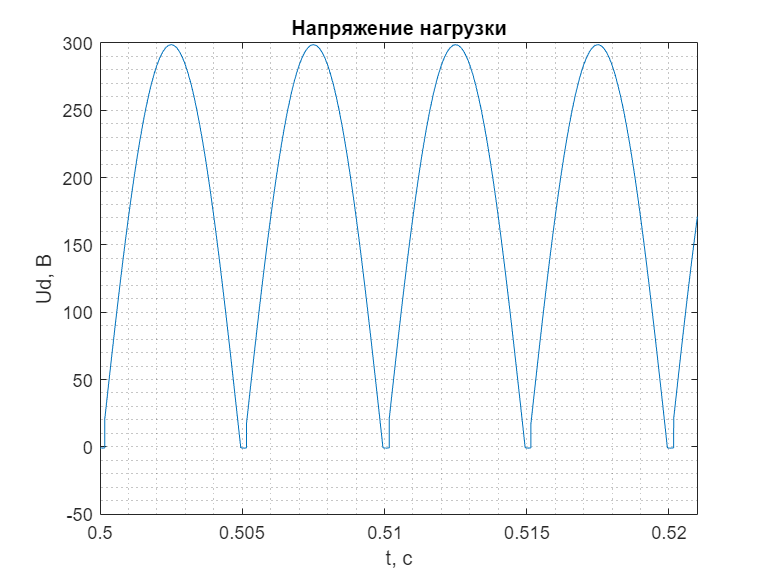

    plot(ScopeVS{4}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Ud, В');
    title('Напряжение нагрузки');
    xlim([0.5 0.521]);

Напряжение и ток на тиристоре управляемого выпрямителя:

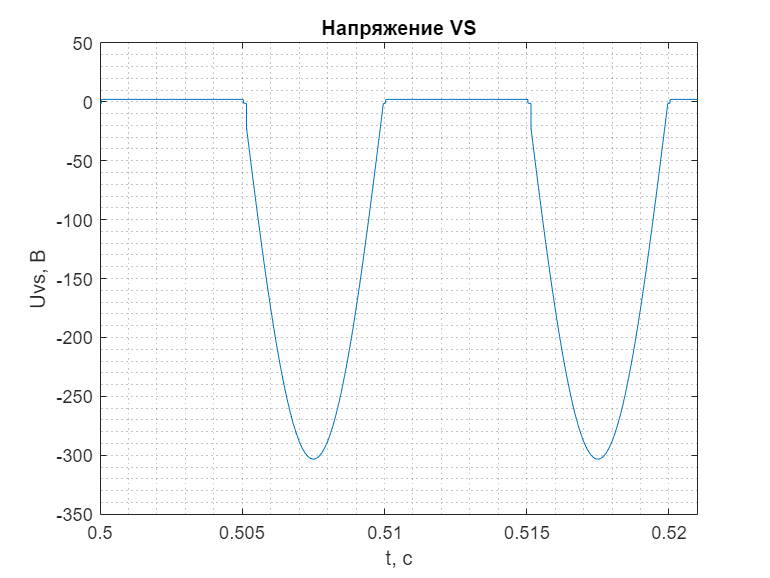

for a = 0
    Angle.Alpha = a;
    sim 'ЛР 2 комп.моделирование'\Lab2Videoblock.slx;
    DCsource.voltage = 0;
    E(end+1) = DCsource.voltage(end, 1);
end    
    plot(ScopeMultimeter{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uvs, В');
    title('Напряжение VS')
    xlim([0.5 0.521]);

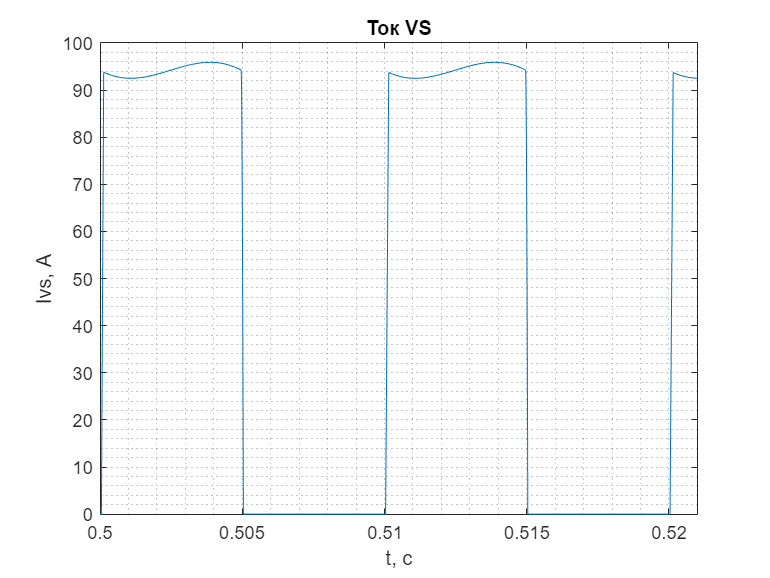

    plot(ScopeMultimeter{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Ivs, А');
    title('Ток VS');
    xlim([0.5 0.521]);

Сигналы системы управления:

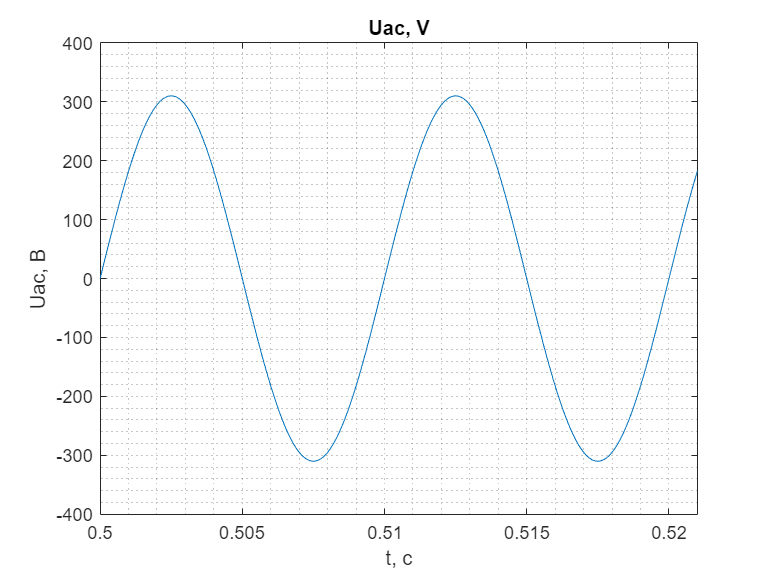

for a = 0
    Angle.Alpha = a;
    sim 'ЛР 2 комп.моделирование'\Lab2Videoblock.slx;
    DCsource.voltage = 0;
    E(end+1) = DCsource.voltage(end, 1);
end
    plot(ScopeData2{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uac, В');
    title('Uac, V');
    xlim([0.5 0.521]);

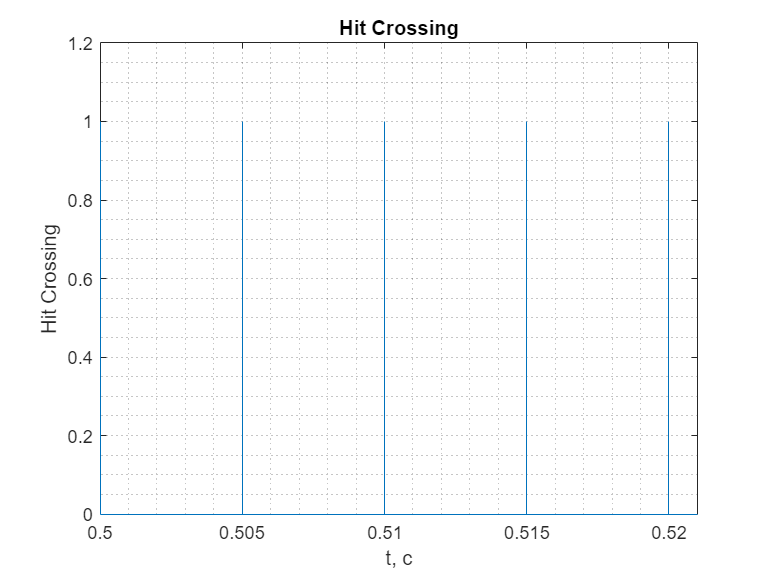

    plot(ScopeData2{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Hit Crossing');
    title('Hit Crossing');
    xlim([0.5 0.521]);
    ylim([0 1.2]); 

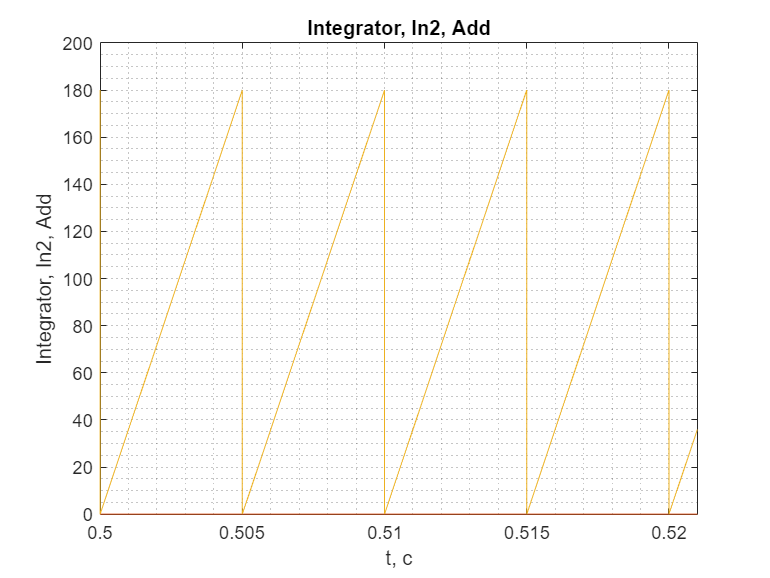

    plot(ScopeData2{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Integrator, In2, Add');
    title('Integrator, In2, Add');
    xlim([0.5 0.521]);

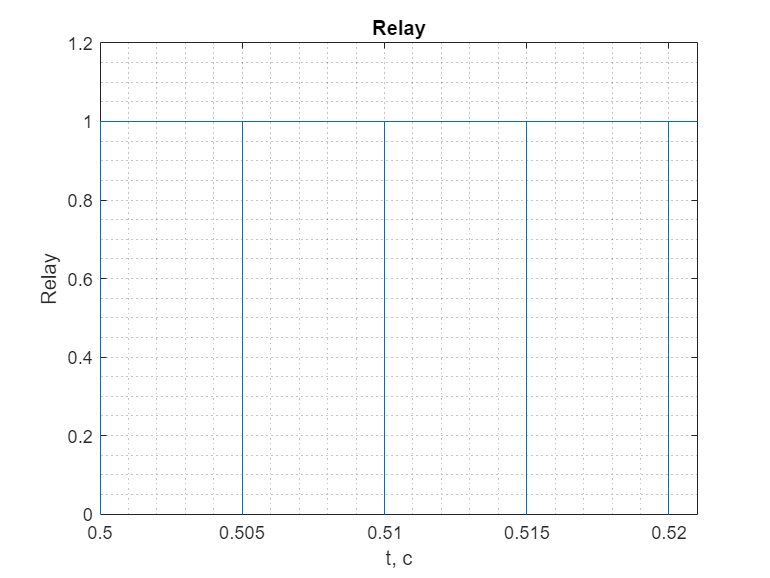

    plot(ScopeData2{4}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Relay');
    title('Relay');
    xlim([0.5 0.521]);
     ylim([0 1.2]); 

При угле альфа = 40 и ЭДС = 0:

Мгновенные токи и напряжение управляемого выпрямителя:

Диаграммы тока на входе трансформатора ,тока обратного диода, тока и напряжения на нагрузке:

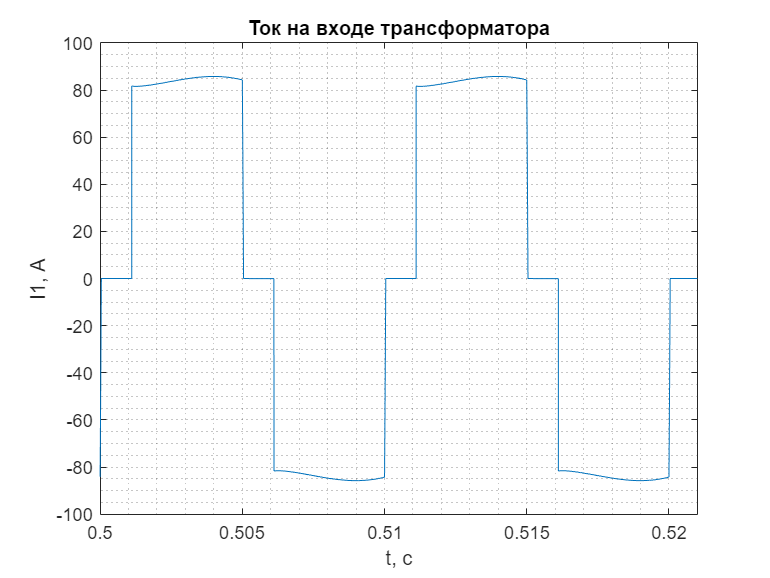

for a = 40
    Angle.Alpha = a;
    sim 'ЛР 2 комп.моделирование'\Lab2Videoblock.slx;
    DCsource.voltage = 0;
    E = DCsource.voltage;
end  
    plot(ScopeVS{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('I1, А');
    title('Ток на входе трансформатора');
    xlim([0.5 0.521]);

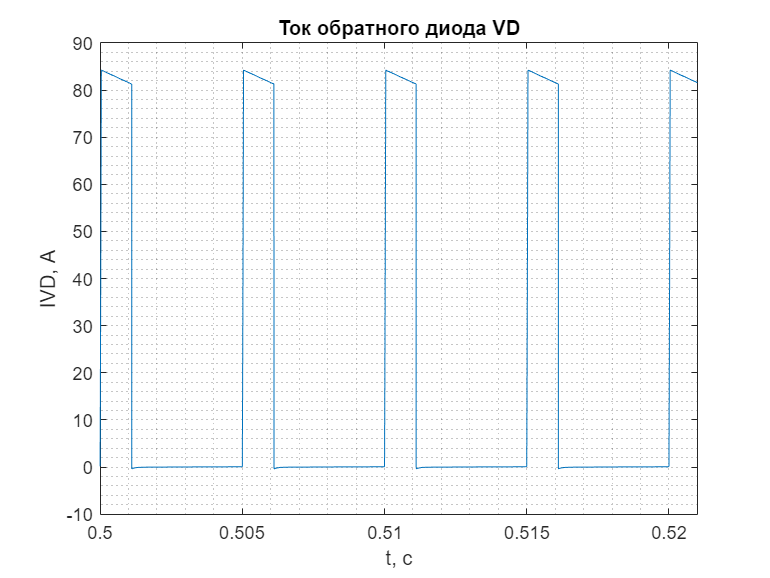

    plot(ScopeVS{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('IVD, А');
    title('Ток обратного диода VD');
    xlim([0.5 0.521]);

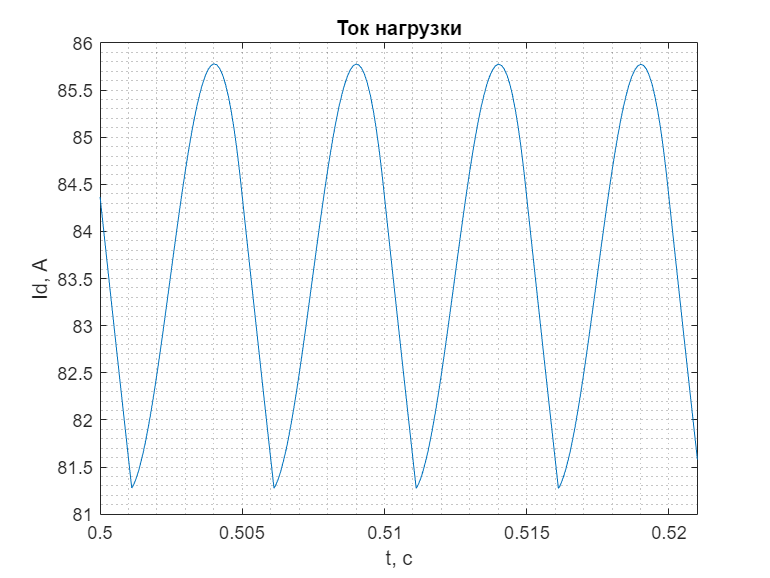

    plot(ScopeVS{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Id, А');
    title('Ток нагрузки');
    xlim([0.5 0.521]);

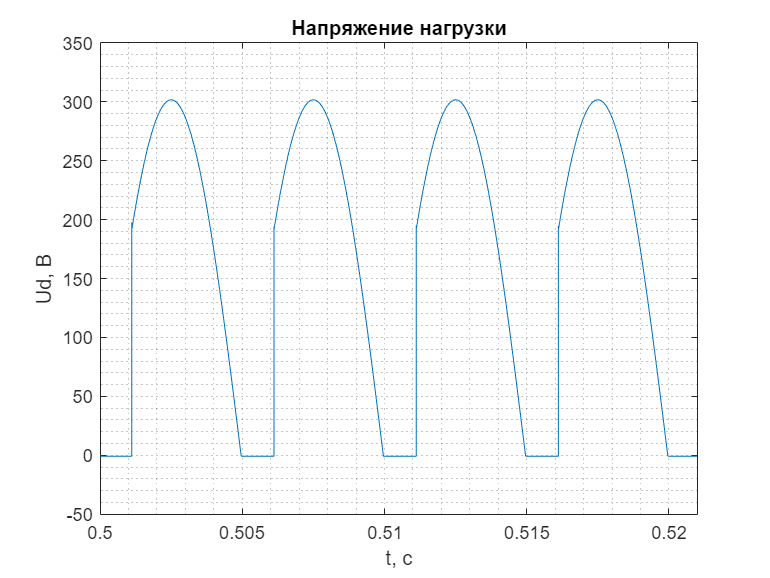

    plot(ScopeVS{4}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Ud, В');
    title('Напряжение нагрузки');
    xlim([0.5 0.521]);

Напряжение и ток на тиристоре управляемого выпрямителя:

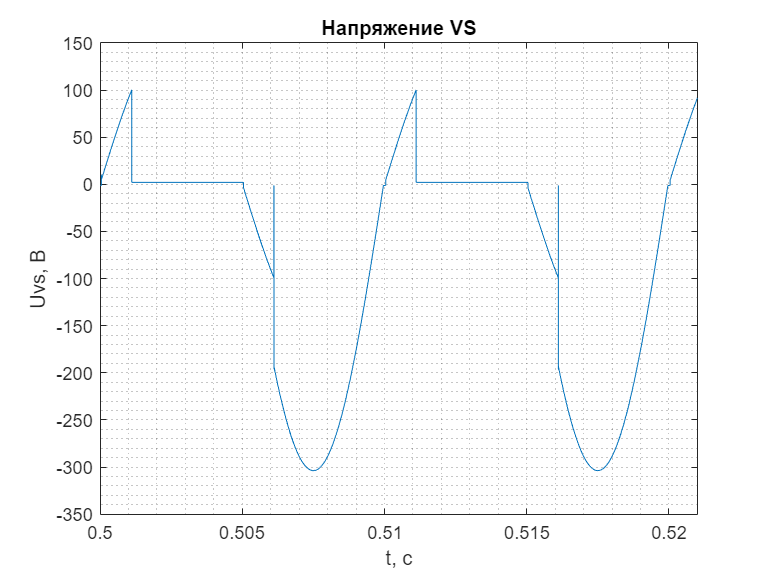

for a = 40
    Angle.Alpha = a;
    sim 'ЛР 2 комп.моделирование'\Lab2Videoblock.slx;
    DCsource.voltage = 0;
    E(end+1) = DCsource.voltage(end, 1);
end    
    plot(ScopeMultimeter{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uvs, В');
    title('Напряжение VS')
    xlim([0.5 0.521]);

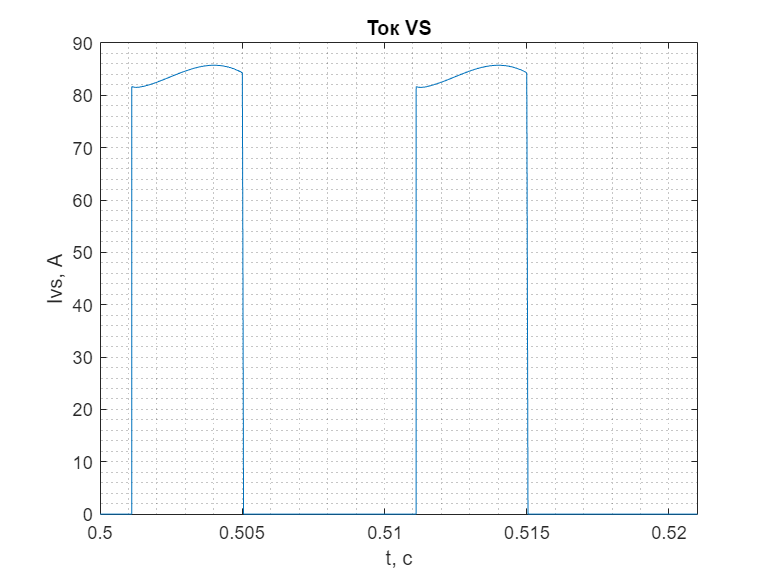

    plot(ScopeMultimeter{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Ivs, А');
    title('Ток VS');
    xlim([0.5 0.521]);

Сигналы системы управления:

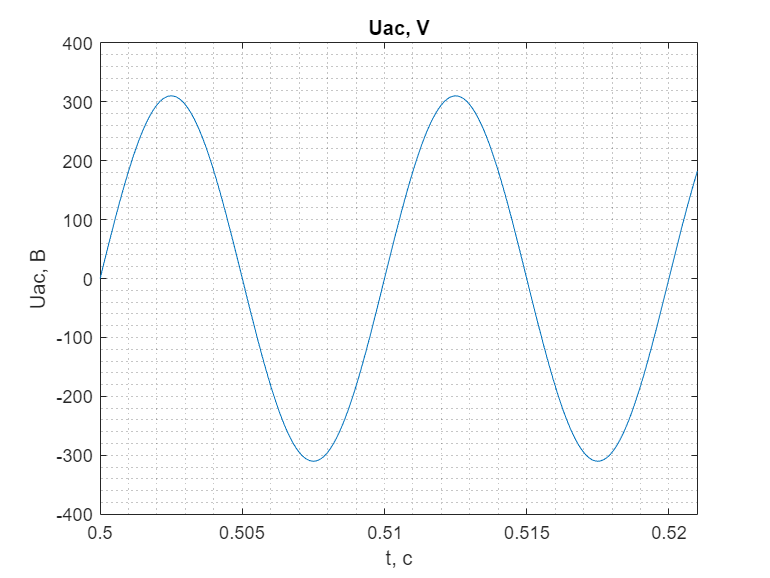

for a = 40
    Angle.Alpha = a;
    sim 'ЛР 2 комп.моделирование'\Lab2Videoblock.slx;
    DCsource.voltage = 0;
    E(end+1) = DCsource.voltage(end, 1);
end
    plot(ScopeData2{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uac, В');
    title('Uac, V');
    xlim([0.5 0.521]);

    plot(ScopeData2{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Hit Crossing');
    title('Hit Crossing');
    xlim([0.5 0.521]);
    ylim([0 1.2]); 

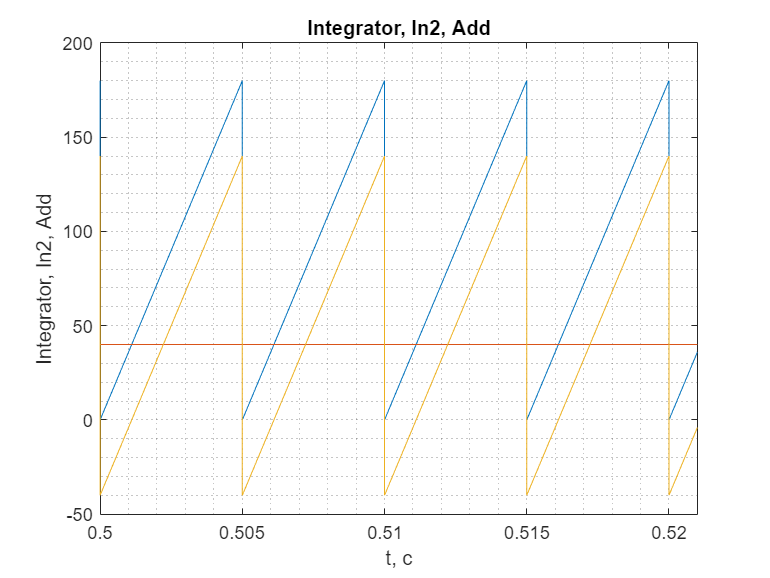

    plot(ScopeData2{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Integrator, In2, Add');
    title('Integrator, In2, Add');
    xlim([0.5 0.521]);

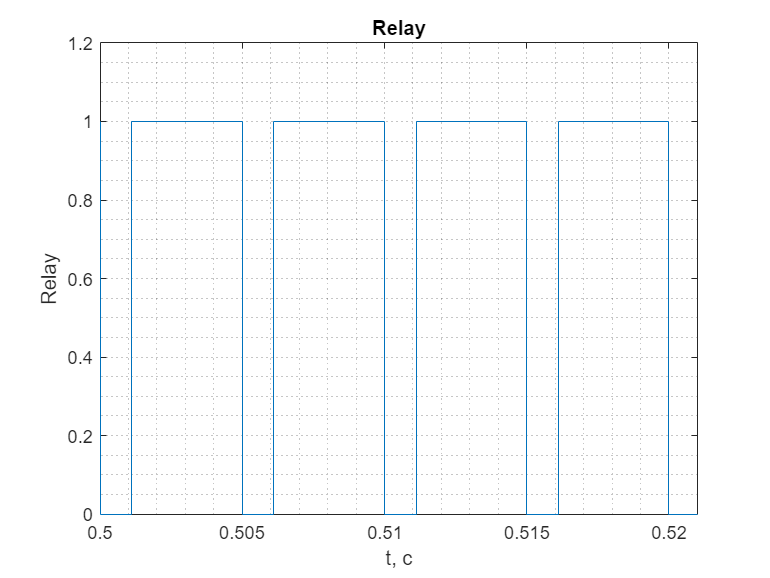

    plot(ScopeData2{4}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Relay');
    title('Relay');
    xlim([0.5 0.521]);
     ylim([0 1.2]); 

При угле альфа = 60 и ЭДС = 0:

Мгновенные токи и напряжение управляемого выпрямителя:

Диаграммы тока на входе трансформатора ,тока обратного диода, тока и напряжения на нагрузке:

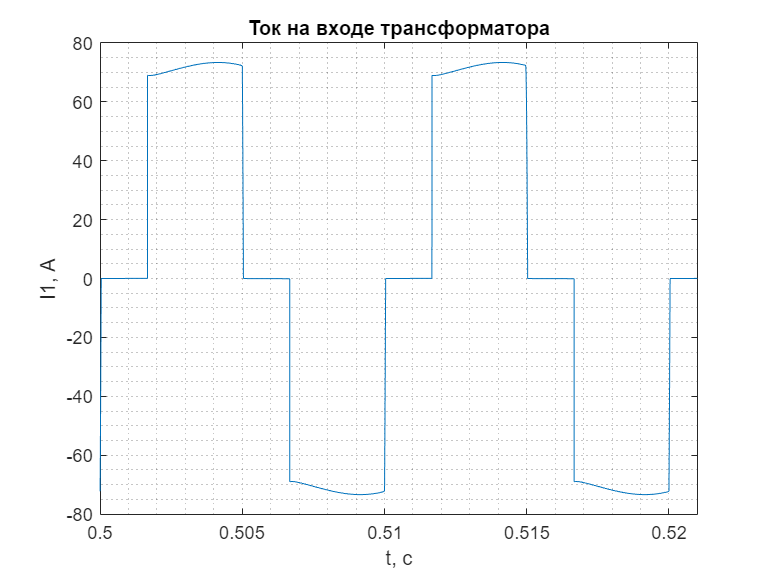

for a = 60
    Angle.Alpha = a;
    sim 'ЛР 2 комп.моделирование'\Lab2Videoblock.slx;
    DCsource.voltage = 0;
    E = DCsource.voltage;
end  
    plot(ScopeVS{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('I1, А');
    title('Ток на входе трансформатора');
    xlim([0.5 0.521]);

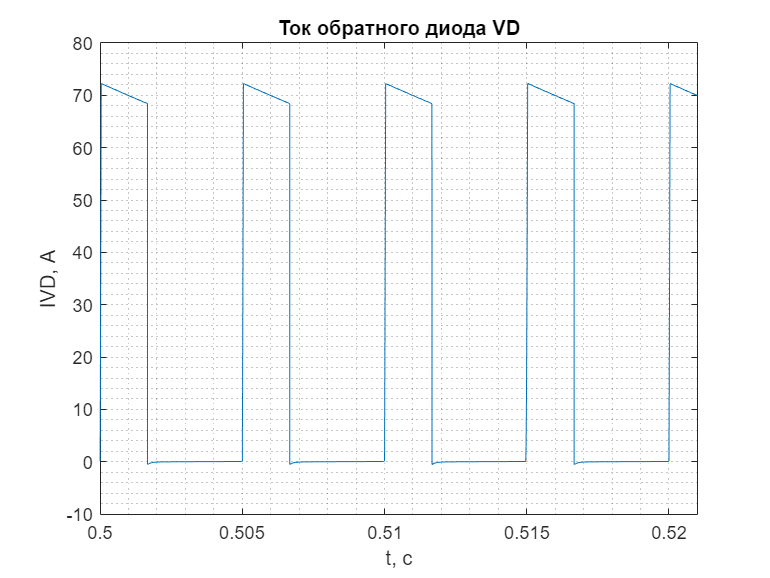

    plot(ScopeVS{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('IVD, А');
    title('Ток обратного диода VD');
    xlim([0.5 0.521]);

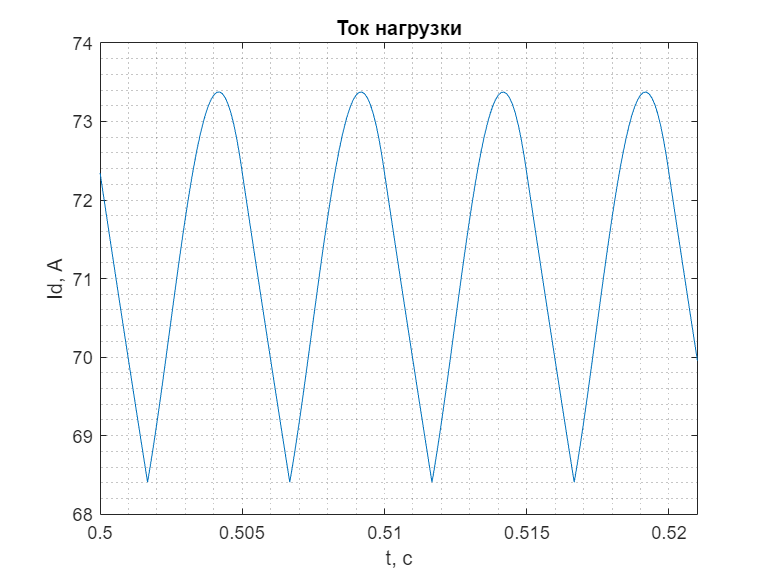

    plot(ScopeVS{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Id, А');
    title('Ток нагрузки');
    xlim([0.5 0.521]);

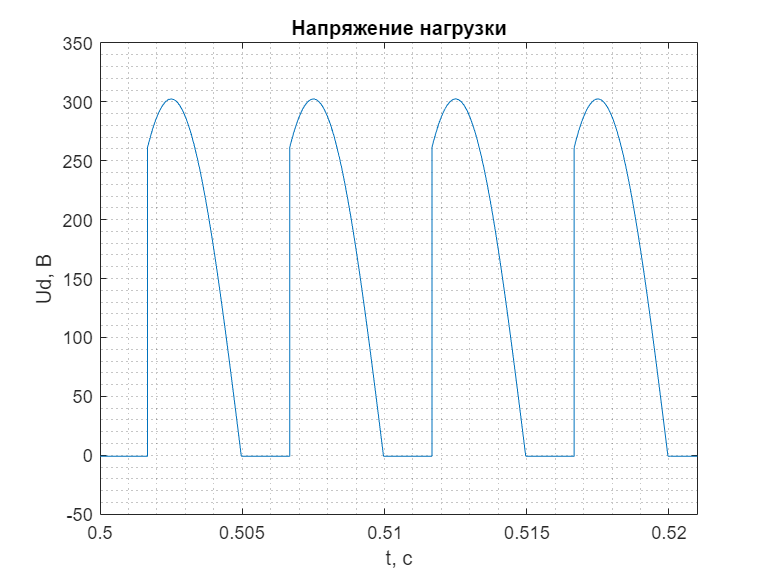

    plot(ScopeVS{4}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Ud, В');
    title('Напряжение нагрузки');
    xlim([0.5 0.521]);

Напряжение и ток на тиристоре управляемого выпрямителя:

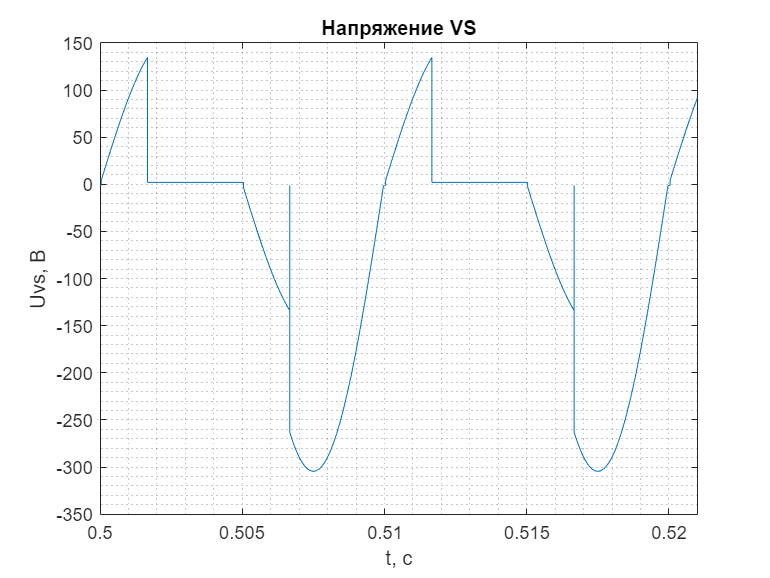

for a = 60
    Angle.Alpha = a;
    sim 'ЛР 2 комп.моделирование'\Lab2Videoblock.slx;
    DCsource.voltage = 0;
    E(end+1) = DCsource.voltage(end, 1);
end    
    plot(ScopeMultimeter{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uvs, В');
    title('Напряжение VS')
    xlim([0.5 0.521]);

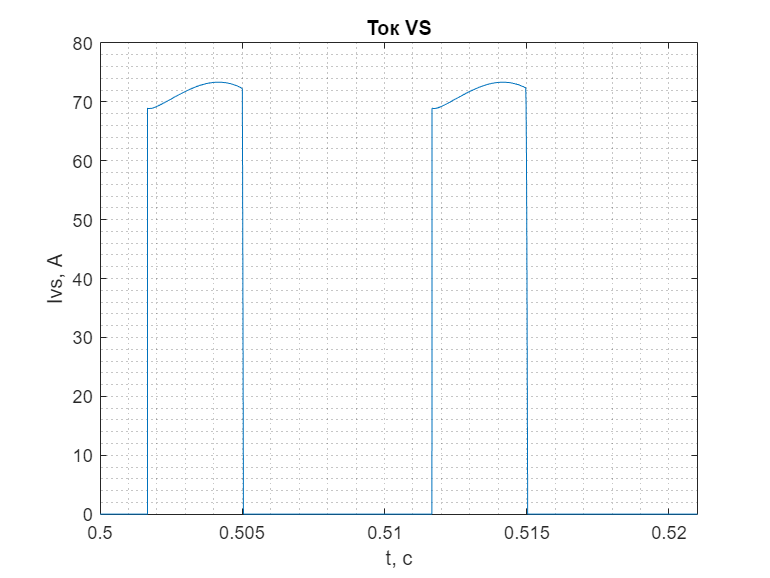

    plot(ScopeMultimeter{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Ivs, А');
    title('Ток VS');
    xlim([0.5 0.521]);

Сигналы системы управления:

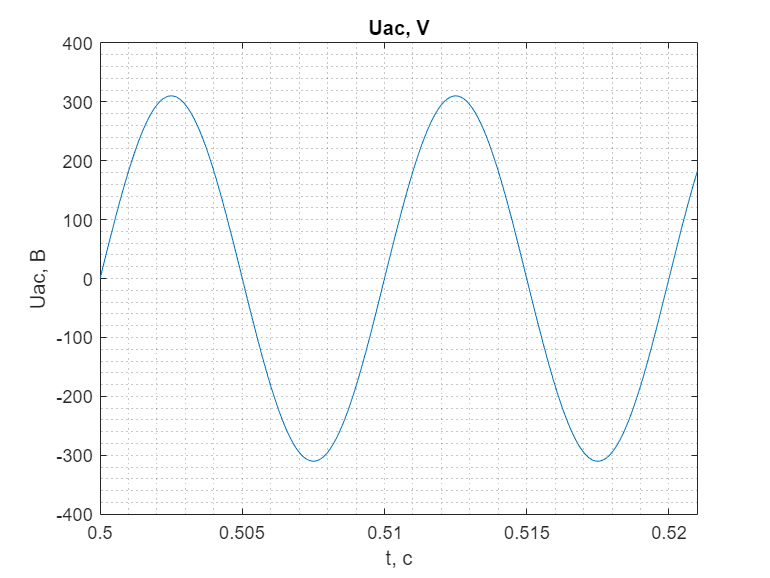

for a = 60
    Angle.Alpha = a;
    sim 'ЛР 2 комп.моделирование'\Lab2Videoblock.slx;
    DCsource.voltage = 0;
    E(end+1) = DCsource.voltage(end, 1);
end
    plot(ScopeData2{1}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Uac, В');
    title('Uac, V');
    xlim([0.5 0.521]);

    plot(ScopeData2{2}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Hit Crossing');
    title('Hit Crossing');
    xlim([0.5 0.521]);
    ylim([0 1.2]); 

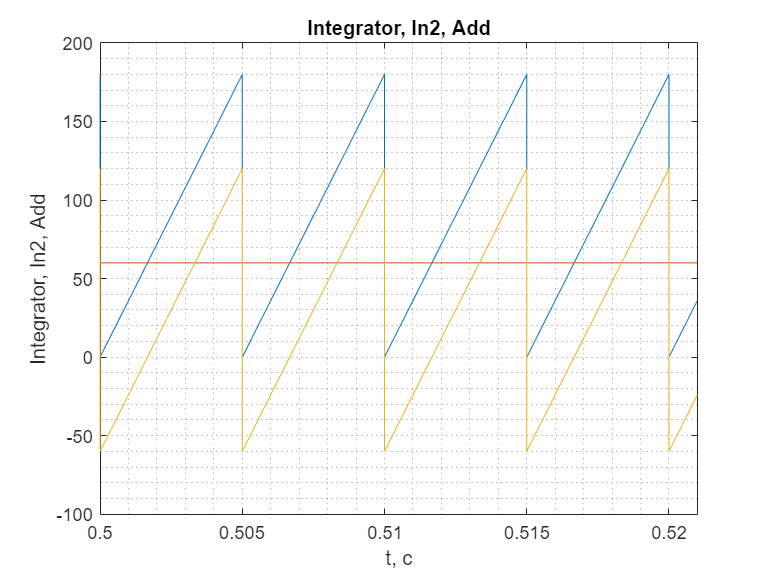

    plot(ScopeData2{3}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Integrator, In2, Add');
    title('Integrator, In2, Add');
    xlim([0.5 0.521]);

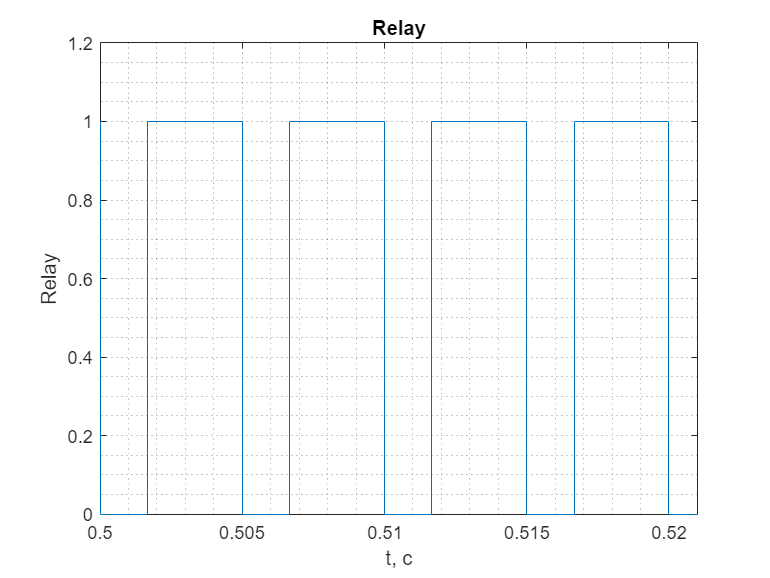

   
    plot(ScopeData2{4}.Values);
    grid("minor");
    xlabel('t, с');
    ylabel('Relay');
    title('Relay');
    xlim([0.5 0.521]);
     ylim([0 1.2]); 

**8. Спектральный анализ тока в цепи питания УВ (ток трансформатора)**

Исследование сигналов управления выпрямителя осуществляем при  одном значении угла управления:

for a = 60
    Angle.Alpha = a;
    sim 'ЛР 2 комп.моделирование'\Lab2Videoblock.slx;
    DCsource.voltage = 0;
    E = DCsource.voltage;
end

Запускаем инструмент спектрального анализа:

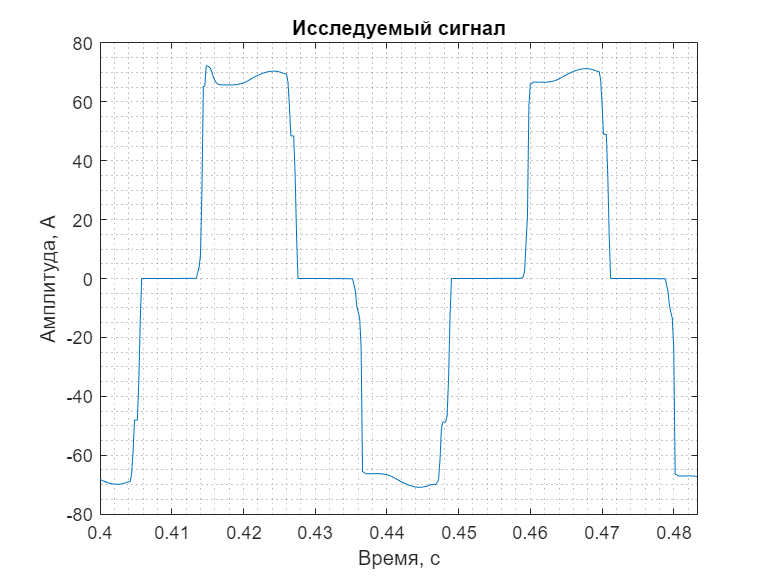

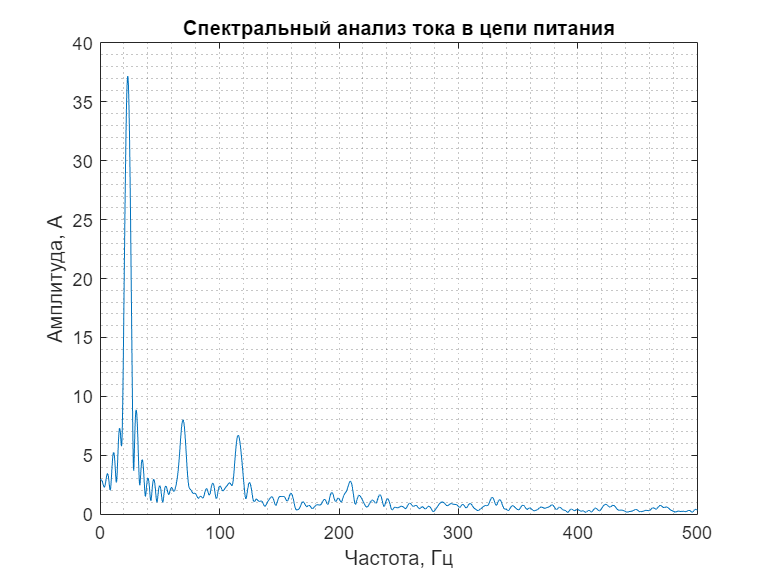

 
currentSpectr = simout;
run("spectral_analys.m");

**9. Вывод**

В ходе лабораторной работы мы исследовали работу однофазного управляемого двухполупериодного выпрямителя при работе на активноин-идуктивную нагрузку. 

*При увеличении противо-э.д.с:*

1) Ток нагрузкиувеличивается, а напряжение нагрузки уменьшается;

2) Мгновенные токи управляемого выпрямителя увеличиваются, а напряжение управляемого выпрямителя остается неизменным; 

3) Полная и активная мощности, потребляемые выпрямителем из сети, увеличиваются; 

4) Мощность на нагрузке также увеличивается; 

5) Потери в тиристоре управляемого выпрямителя увеличиваются. 

*При увеличении угла α:*

1) Ток нагрузки и напряжение нагрузки уменьшаются; 

2) Мгновенные токи управляемого выпрямителя уменьшаются, а напряжение управляемого выпрямителя остается неизменной; 

3) Полная и активная мощности, потребляемые выпрямителем из сети, уменьшаются;

4) Мощность на нагрузке также уменьшается; 

5) Потери в тиристоре управляемого выпрямителя уменьшаются.

*Спектральный анализ тока в цепи питания УВ (ток трансформатора):*

При исследовании сигнала управления выпрямителем (Спектрального анализа) (тока на входе трансформатора), выявлено, что наибольшая амплитуда сигнала равна 35,4 А при частоте сигнала равном 20 Гц.